
%Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=6;             % Tiempo de simulación en segundos (s)
ts=0.009;           % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=-9;  %Posición inicial eje x
y1(1)=10;  %Posición inicial eje y
phi(1)=4.712389 ; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Ecuaciones paramétricas de la trayectoria deseada
%a)Circulo
%hxd=8*cos(0.2*t);
%hyd=8*sin(0.4*t);

%flor incompleta.
%hxd = 5*cos(8*t).*cos(t); 
%hyd = 5*cos(8*t).*sin(t); 

%hexagono
%---------------------- Nueva trayectoria hexágono ---------------------
%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Puntos a seguir
tray_x = [-9, -7, -2, 3, 5, -9];
tray_y = [10, 1, -10, 1, 10, 10];
num_puntos = length(tray_x);

% Duración total y de cada segmento
segment_time = tf / (num_puntos - 1); % Tiempo por segmento
hxd = zeros(1, N);
hyd = zeros(1, N);

% Construcción de trayectoria deseada por tramos lineales
for i = 1:num_puntos - 1
    idx = (t >= (i - 1) * segment_time) & (t < i * segment_time);
    dt = t(idx) - (i - 1) * segment_time;
    dur = segment_time;

    % Interpolación lineal
    hxd(idx) = tray_x(i) + (tray_x(i + 1) - tray_x(i)) / dur * dt;
    hyd(idx) = tray_y(i) + (tray_y(i + 1) - tray_y(i)) / dur * dt;
end

% Asegurarse de que el último punto se asigna correctamente
hxd(t >= (num_puntos - 1) * segment_time) = tray_x(end);
hyd(t >= (num_puntos - 1) * segment_time) = tray_y(end);

% Derivadas aproximadas de la trayectoria deseada (velocidades deseadas)
hxdp = [diff(hxd) 0] / ts;
hydp = [diff(hyd) 0] / ts;

%---------------------------------------------------------------------- 

Trayectoria

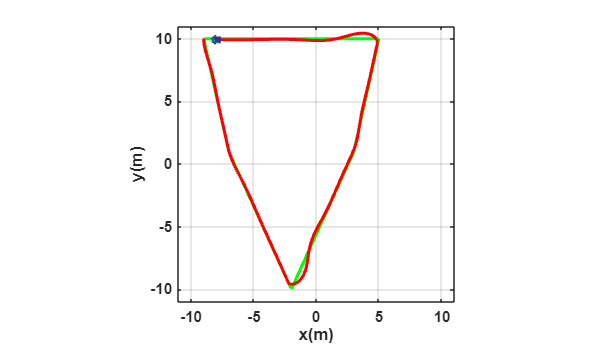


%hxd= ones(1,7).*cos(t);
%hyd=ones(1,7).*sin(t);

%corazón 
%hxd = 12*sin(t)-4*sin(3*t);
%hyd = 13*cos(t)-5*cos(2*t)-2*cos(3*t)-4*cos(16);

%Velocidades de la trayectoria deseada
hxdp= -4*0.2*sin(0.2*t);
hydp= 4*0.4*cos(0.4*t);



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[13 0;...
       0 13];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-11 11 -11 11 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

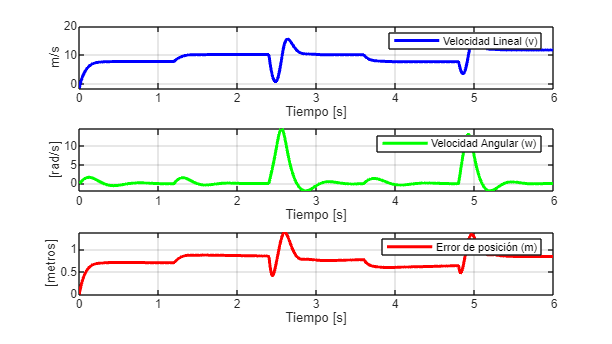

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');